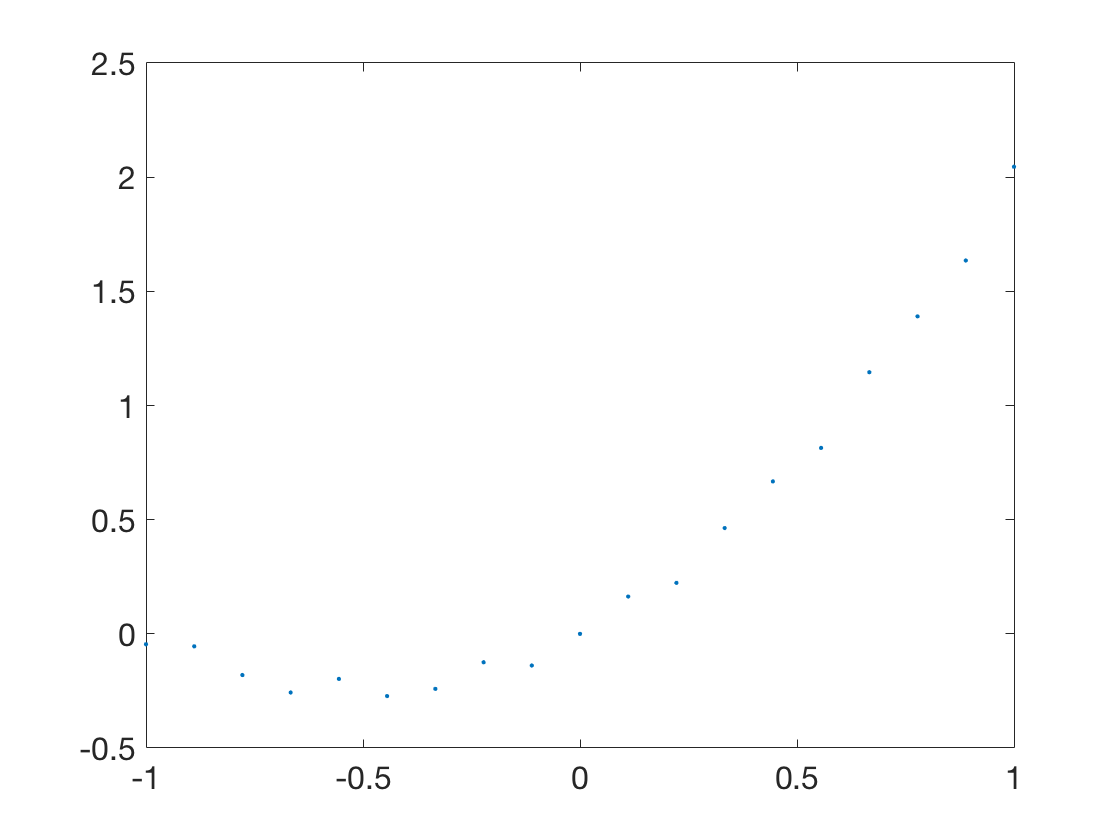

n = 18;
t = linspace(-1,1,n+1)';  y = t.^2 + t + 0.05*sin(20*t);
clf, plot(t,y,'.')

By default `interp1` gives us an interpolating function that is linear between each pair of consecutive nodes.

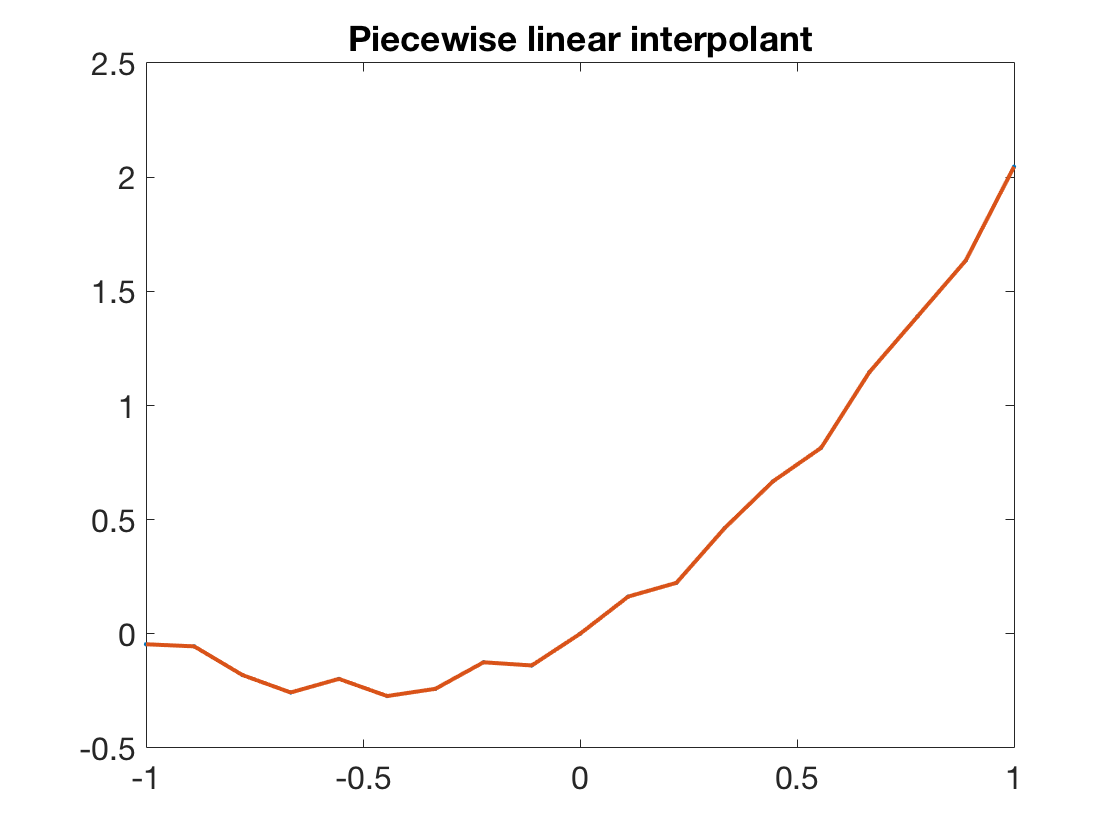

x = linspace(-1,1,400)';
hold on, plot(x,interp1(t,y,x))
title('Piecewise linear interpolant')    % ignore this line

We may instead request a smoother interpolant that is piecewise cubic.

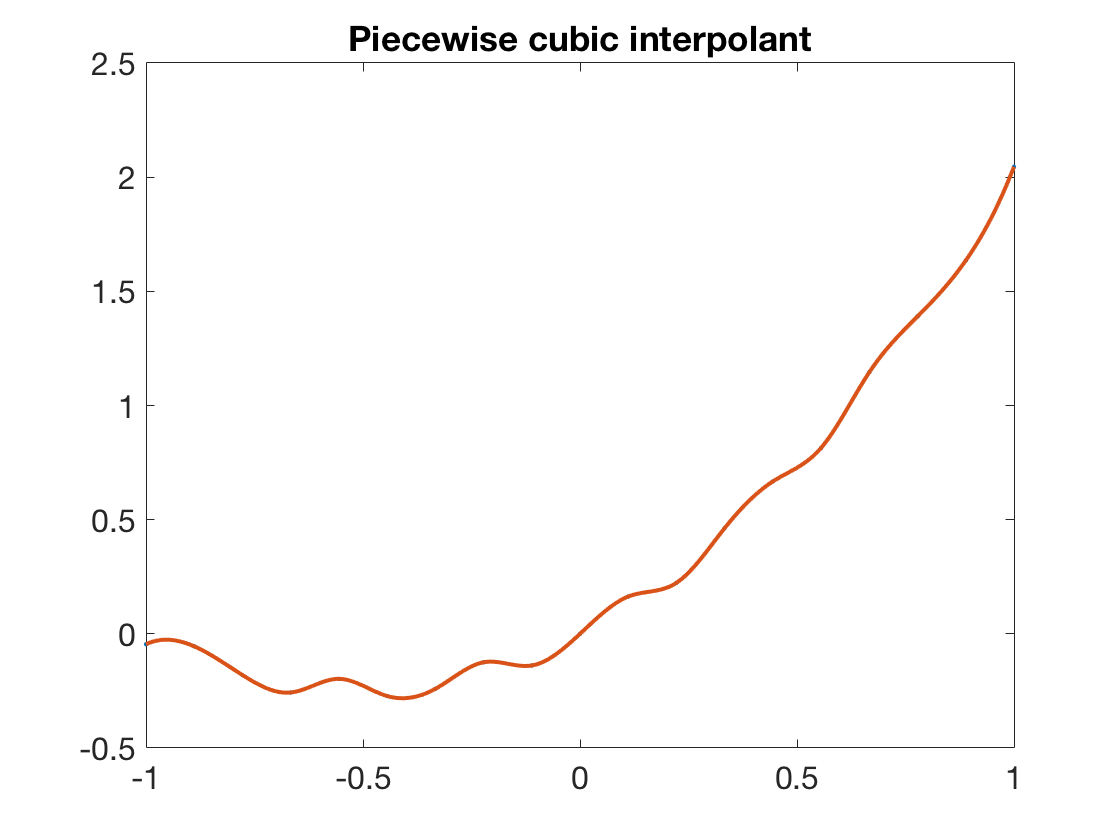

cla
plot(t,y,'.')
plot(x,interp1(t,y,x,'spline'))
title('Piecewise cubic interpolant')   % ignore this line